## cse327 hw4

Zian Shang

- Notes: 

- 1. Should only select points clockwise or counter-clockwise, the code below do not check whether the newly selected point is between previous points.

- 2. The selected x and y values should within the range of 0~180.

- Issue: Normalization. This code uses nested for loops to continuously calculate Es, Ec, and Eg for each neighbor of contour point and switch pointer to the neighbor with smaller Energy value. It does not remember previously calculated values, thus cannot find maxima and minima used for normalization. 

Read original image first. 

inputImage = imread("SampleImage.png");
% Define text and font settings
imshow(inputImage);

Try to select points on input image and display.

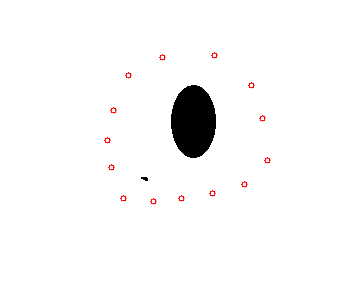

% Initialize variables
point_matrix = []; % Matrix to store selected points

while true
    % Wait for the user to click a point
    [x, y] = ginput(1);
    
    % Check if the user has closed the figure
    if isempty(x) || isempty(y)
        break;
    end
    
    % Store the selected point in the matrix
    point_matrix = [point_matrix; x, y];
    
    % Plot the new point
    hold on;
    plot(x, y, 'ro', 'MarkerSize', 3); % Display the point as a red circle
    hold off;
end

% View all selected points x y

   24.0000   82.0000
   39.0000   47.0000
   73.0000   29.0000
  125.0000   27.0000
  162.0000   57.0000
  173.0000   90.0000
  178.0000  132.0000
  155.0000  156.0000
  123.0000  165.0000
   92.0000  170.0000
   64.0000  173.0000
   34.0000  170.0000
   22.0000  139.0000
   18.0000  112.0000



disp(point_matrix);

% Several values to set
f = 0;
halfwid = 1; % 3 by 3 neighborhood
currentFraction = 1;  % Initial fraction value for while loop to start
pointCount = height(point_matrix);    % Obtain the number of points for calculating moving fraction in each round

% Calculate initial average distance between consecutive points
differences = diff(point_matrix);
first_to_last_distance = norm(point_matrix(1, :) - point_matrix(end, :));
total_distance = [sqrt(sum(differences.^2, 2)); first_to_last_distance];
d = mean(total_distance);

   35.7591



disp(d);

Start looping to move points in point_matrix.

% Create a while loop for each iteration of selected points
while currentFraction > f
    moves = 0;      % Number of points moved in one round

    % Loop through each selected point
    for i = 1:pointCount
        pX = point_matrix(i, 1);          % Get x and y values at point i
        pY = point_matrix(i, 2);

        % calculate the current Energy value of point i, EnergyI
        EnergyI = Econtinuity(point_matrix, i, pX, pY, d)+Esmoothness(point_matrix, i, pX, pY)+Eedgebased(inputImage, pX, pY);

        for u = -halfwid:halfwid          % loop through each neighbor
            for v = -halfwid:halfwid
                nX = pX+u;                         % get neighbor x and y values
                nY = pY+v; 

                % Calculate current neighbor Energy value, EnergyN
                % Ec for continuity, Es for smoothness, Eg for edgeness
                EnergyN = Econtinuity(point_matrix, i, nX, nY, d)+Esmoothness(point_matrix, i, nX, nY)+Eedgebased(inputImage, nX, nY);

                % If neighbor E value < point i E value, 
                %  then pX = nX, pY = nY
                if EnergyN < EnergyI
                    EnergyI = EnergyN; 
                    pX = nX;
                    pY = nY; 
                end
            end
        end

        %If pX != point_matrix(i, 1) || pY != point_matrix(i, 2)
        % then point_matrix(i, 1)=pX, point_matrix(i, 2) = pY, moves++
        if pX ~= point_matrix(i, 1) || pY ~= point_matrix(i, 2)
            point_matrix(i, 1) = pX;
            point_matrix(i, 2) = pY;
            moves = moves +1;
        end
    end
    % Update d
    differences = diff(point_matrix);
    first_to_last_distance = norm(point_matrix(1, :) - point_matrix(end, :));
    total_distance = [sqrt(sum(differences.^2, 2)); first_to_last_distance];
    d = mean(total_distance);
    
    % Update current fraction of moved points
    currentFraction = moves/pointCount;

end

% View all selected points x y
disp(point_matrix);

   83.0000   80.0000
   87.0000   70.0000
   95.0000   60.0000
  117.0000   64.0000
  125.0000   80.0000
  126.0000   96.0000
  123.0000  112.0000
  115.0000  124.0000
  101.0000  129.0000
   93.0000  124.0000
   87.0000  116.0000
   84.0000  109.0000
   82.0000  100.0000
   82.0000   90.0000



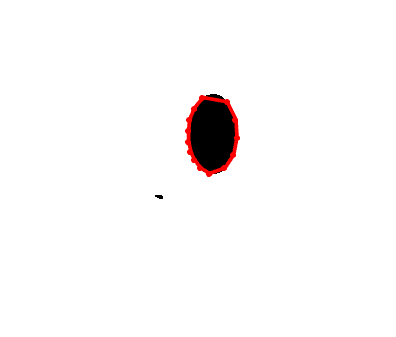

% Plot the outcome point_matrix on the image
figure;
imshow(inputImage);
hold on;
    
% Plot the points
plot(point_matrix(:, 1), point_matrix(:, 2), 'r.', 'MarkerSize', 10);

% Connect adjacent points to form a closed boundary
x = [point_matrix(:, 1); point_matrix(1, 1)];
y = [point_matrix(:, 2); point_matrix(1, 2)];
plot(x, y, 'r', 'LineWidth', 2);

% Connect the first and last points to close the boundary
plot([point_matrix(1, 1), point_matrix(end, 1)], [point_matrix(1, 2), point_matrix(end, 2)], 'r', 'LineWidth', 2);

hold off;

% Implement Ec, Es, Eg functions below

function Ec = Econtinuity(point_matrix, i, pX, pY, d)
    % Find the prev point using i-1
    if(i==1)
        prev_x = point_matrix(height(point_matrix), 1);
        prev_y = point_matrix(height(point_matrix), 2);
    else
        prev_x = point_matrix(i-1, 1);
        prev_y = point_matrix(i-1, 2);
    end

    % Calculate distance between current point and previous point
    distance = sqrt((pX-prev_x)^2+(pY-prev_y)^2);

    Ec = (d-distance)^2; 
end

function Es = Esmoothness(point_matrix, i, pX, pY)

    % Find the prev point using i-1
    if(i==1)
        prev_x = point_matrix(height(point_matrix), 1);
        prev_y = point_matrix(height(point_matrix), 2);
    else
        prev_x = point_matrix(i-1, 1);
        prev_y = point_matrix(i-1, 2);
    end

    % Find the next point using i+1
    if(i == height(point_matrix))
        next_x = point_matrix(1,1);
        next_y = point_matrix(1,2);
    else
        next_x = point_matrix(i+1, 1);
        next_y = point_matrix(i+1, 2);
    end

    Es = (prev_x-2*pX+next_x)^2+(prev_y-2*pY+next_y)^2;

end

function Eg = Eedgebased(inputImage,pX, pY)
    % Calculate x and y gradients of the inputImage
    [dx, dy]=gradient(double(inputImage));
    % Take x and y gradients at the given point
    deltaI = [dx(round(pY), round(pX)), dy(round(pY), round(pX))];
    % calculate the magnitude of gradient
    maginitude = norm(deltaI);

    Eg = -maginitude;
end